# Antenna Pattern of Earth Station

### Rec ITU-R S.465-5: APEREC013V01

[https://www.itu.int/en/ITU-R/software/Pages/ant-pattern.aspx](https://www.itu.int/en/ITU-R/software/Pages/ant-pattern.aspx)

clc
clear all

lambda = 3e8/28e9; % wavelength
G_max = 33; % dB
eta = 0.7; % efficiency

D_lambda = sqrt(10^(G_max/10)/(eta*pi^2))

D_lambda = 16.9942

G_1 = -18 + 25*log10(D_lambda)

G_1 = 12.7575

phi_m = 20.0*sqrt(G_max - G_1)/D_lambda

phi_m = 5.2949

phi_r = 100/D_lambda

phi_r = 5.8844

phi_b = 10^(42/25)

phi_b = 47.8630

syms phi G

G(phi) = piecewise(...
    -phi_m<= phi < phi_m, G_max - 2.5*1e-3*(D_lambda*phi)^2, ...
    phi_m < phi < phi_r, G_1, ...
    phi_r < phi < phi_b, 32 - 25*log10(phi), ...
    phi_b < phi <= 180, -10, ...
    -phi_r <= phi < -phi_m, G_1, ...
    -phi_b <= phi < -phi_r, 32 - 25*log10(-phi), ...
    -180 <= phi < -phi_b, -10);

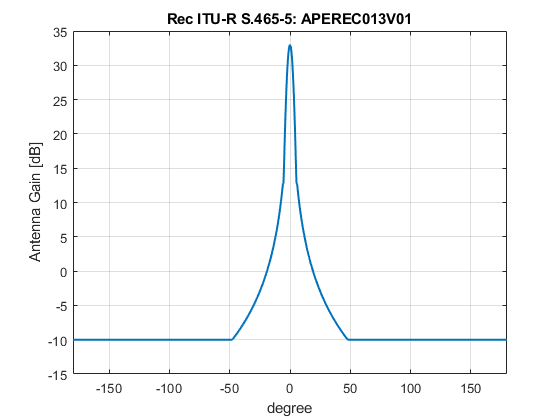

figure
fplot(phi, G, [-180, 180], 'LineWidth', 1.5)
xlabel('degree')

ylabel('Antenna Gain [dB]')
ylim([-15, 35])
title('Rec ITU-R S.465-5: APEREC013V01')
grid on
box on

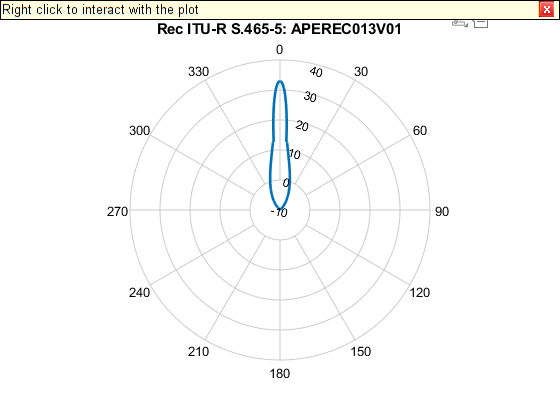


theta = (-1:.001:1)*180;
G1 = G(theta);
figure;
polarpattern(theta, double(G1), ...
    'AngleDirection','cw','AngleAtTop',0, ...
    'AngleResolution', 30, 'LineWidth', 2, ...
    'TitleTop', 'Rec ITU-R S.465-5: APEREC013V01')

theta_vec_save = rad2deg(linspace(0, pi));
G_vec = G(theta_vec_save);
csvwrite("D:\Satellites\28GHz\data\gain.csv", G_vec)
